# Homework 3

Kathryn Atherton

ABE 30100

February 25, 2019

Assume you are recently hired by TAOCO’s distillation division.  This division uses distillation to produce high ethanol concentration beverages made from TAOCO’s whiskey product, which contains 30 mol% water.  The whiskey feedstock has an ethanol concentration of 30 mol % water.  It is to be distilled at 180 mm Hg to produce Knockout™, a higher ethanol composition product (see diagram below).  

Assume the set of data below are measurements of vapor-liquid equilibrium values for binary mixtures of water and ethanol at the fixed distillation temperature.  P is the total pressure (mm Hg), L is the liquid water mole fraction equilibrium composition data, and V is the vapor water mole fraction equilibrium composition data.

**Part A**

Create cubic spline numerical models for the vapor-liquid equilibrium curves for this binary system and **provide an appropriate plot of P vs. water molar composition.**

P = [136, 145, 153.5, 161.4, 168.5, 175.3, 186.5, 195.6, 200.5, 204.9, 209.5, 213.5, ...
    216.4, 218.9, 221.3, 223.4, 225, 225.5, 225.1, 222.7, 220, 216.6, 213.7, 210.7, ...
    208.6, 205.5, 202];
L = [0, 0.025, 0.05, 0.075, 0.1, 0.125, 0.175, 0.231, 0.27, 0.3121, 0.37, 0.409, 0.445,...
    0.486, 0.5349, 0.5912, 0.65, 0.715, 0.7597, 0.8289, 0.87, 0.9058, 0.935, 0.9565, ...
    0.97, 0.985, 1];
V = [0, 0.1, 0.2, 0.3, 0.37, 0.43, 0.51, 0.55, 0.58, 0.60, 0.62, 0.63, 0.64, 0.65, 0.66,...
    0.67, 0.68, 0.69, 0.70, 0.72, 0.75, 0.79, 0.81, 0.85, 0.87, 0.91, 1];

fprintf('Spline Equations for Vapor Content:')

Spline Equations for Vapor Content:

PV = cubic_spline(V,P);

Valid from x = 0.0000 to 0.1000

$$f = -49.274\,x^{3}+90.493\,x+136.0$$

Valid from x = 0.1000 to 0.2000

$$f = 89.015\,x-14.782\,{\left(x-0.1\right)}^{2}-253.63\,{\left(x-0.1\right)}^{3}+136.1$$

Valid from x = 0.2000 to 0.3000

$$f = 78.449\,x-90.871\,{\left(x-0.2\right)}^{2}+963.79\,{\left(x-0.2\right)}^{3}+137.81$$

Valid from x = 0.3000 to 0.3700

$$f = 89.189\,x+198.27\,{\left(x-0.3\right)}^{2}-334.46\,{\left(x-0.3\right)}^{3}+134.64$$

Valid from x = 0.3700 to 0.4300

$$f = 112.03\,x+128.03\,{\left(x-0.37\right)}^{2}-1771.7\,{\left(x-0.37\right)}^{3}+127.05$$

Valid from x = 0.4300 to 0.5100

$$f = 108.26\,x-190.87\,{\left(x-0.43\right)}^{2}+7345.5\,{\left(x-0.43\right)}^{3}+128.75$$

Valid from x = 0.5100 to 0.5500

$$f = 218.75\,x+1572.0\,{\left(x-0.51\right)}^{2}-33833.0\,{\left(x-0.51\right)}^{3}+74.937$$

Valid from x = 0.5500 to 0.5800

$$f = 182.11\,x-2488.0\,{\left(x-0.55\right)}^{2}+62064.0\,{\left(x-0.55\right)}^{3}+95.437$$

Valid from x = 0.5800 to 0.6000

$$f = 200.41\,x+3097.8\,{\left(x-0.58\right)}^{2}-105911.0\,{\left(x-0.58\right)}^{3}+84.263$$

Valid from x = 0.6000 to 0.6200

$$f = 197.23\,x-3256.9\,{\left(x-0.6\right)}^{2}+244799.0\,{\left(x-0.6\right)}^{3}+86.564$$

Valid from x = 0.6200 to 0.6300

$$f = 360.69\,x+11430.0\,{\left(x-0.62\right)}^{2}-749844.0\,{\left(x-0.62\right)}^{3}-14.125$$

Valid from x = 0.6300 to 0.6400

$$f = 364.33\,x-11065.0\,{\left(x-0.63\right)}^{2}+363244.0\,{\left(x-0.63\right)}^{3}-16.028$$

Valid from x = 0.6400 to 0.6500

$$f = 251.99\,x-168.27\,{\left(x-0.64\right)}^{2}-3108.7\,{\left(x-0.64\right)}^{3}+55.124$$

Valid from x = 0.6500 to 0.6600

$$f = 247.7\,x-261.53\,{\left(x-0.65\right)}^{2}-50803.0\,{\left(x-0.65\right)}^{3}+57.898$$

Valid from x = 0.6600 to 0.6700

$$f = 227.22\,x-1785.6\,{\left(x-0.66\right)}^{2}+6320.0\,{\left(x-0.66\right)}^{3}+71.332$$

Valid from x = 0.6700 to 0.6800

$$f = 193.41\,x-1596.0\,{\left(x-0.67\right)}^{2}-174499.0\,{\left(x-0.67\right)}^{3}+93.817$$

Valid from x = 0.6800 to 0.6900

$$f = 109.14\,x-6830.3\,{\left(x-0.68\right)}^{2}+91589.0\,{\left(x-0.68\right)}^{3}+150.78$$

Valid from x = 0.6900 to 0.7000

$$f = 0.01447\,x-4082.7\,{\left(x-0.69\right)}^{2}+8121.7\,{\left(x-0.69\right)}^{3}+225.49$$

Valid from x = 0.7000 to 0.7200

$$f = 89956.0\,{\left(x-0.7\right)}^{3}-3839.0\,{\left(x-0.7\right)}^{2}-79.202\,x+280.54$$

Valid from x = 0.7200 to 0.7500

$$f = 1558.4\,{\left(x-0.72\right)}^{2}-124.82\,x-13262.0\,{\left(x-0.72\right)}^{3}+312.57$$

Valid from x = 0.7500 to 0.7900

$$f = 364.78\,{\left(x-0.75\right)}^{2}-67.121\,x-20294.0\,{\left(x-0.75\right)}^{3}+270.34$$

Valid from x = 0.7900 to 0.8100

$$f = 79399.0\,{\left(x-0.79\right)}^{3}-2070.5\,{\left(x-0.79\right)}^{2}-135.35\,x+323.53$$

Valid from x = 0.8100 to 0.8500

$$f = 2693.4\,{\left(x-0.81\right)}^{2}-122.89\,x-37404.0\,{\left(x-0.81\right)}^{3}+313.24$$

Valid from x = 0.8500 to 0.8700

$$f = 44642.0\,{\left(x-0.85\right)}^{3}-1795.1\,{\left(x-0.85\right)}^{2}-86.956\,x+284.61$$

Valid from x = 0.8700 to 0.9100

$$f = 883.48\,{\left(x-0.87\right)}^{2}-105.19\,x-4782.4\,{\left(x-0.87\right)}^{3}+300.11$$

Valid from x = 0.9100 to 1.0000

$$f = 309.59\,{\left(x-0.91\right)}^{2}-57.464\,x-1146.6\,{\left(x-0.91\right)}^{3}+257.79$$

hold on;
fprintf('Spline Equations for Liquid Content:')

Spline Equations for Liquid Content:

PL = cubic_spline(L,P);

Valid from x = 0.0000 to 0.0250

$$f = -6755.5\,x^{3}+364.22\,x+136.0$$

Valid from x = 0.0250 to 0.0500

$$f = 351.56\,x-506.66\,{\left(x-0.025\right)}^{2}+1777.5\,{\left(x-0.025\right)}^{3}+136.21$$

Valid from x = 0.0500 to 0.0750

$$f = 329.56\,x-373.35\,{\left(x-0.05\right)}^{2}-6754.5\,{\left(x-0.05\right)}^{3}+137.02$$

Valid from x = 0.0750 to 0.1000

$$f = 298.22\,x-879.94\,{\left(x-0.075\right)}^{2}+12440.0\,{\left(x-0.075\right)}^{3}+139.03$$

Valid from x = 0.1000 to 0.1250

$$f = 277.55\,x+53.096\,{\left(x-0.1\right)}^{2}-11007.0\,{\left(x-0.1\right)}^{3}+140.74$$

Valid from x = 0.1250 to 0.1750

$$f = 259.57\,x-772.45\,{\left(x-0.125\right)}^{2}+1221.6\,{\left(x-0.125\right)}^{3}+142.85$$

Valid from x = 0.1750 to 0.2310

$$f = 191.49\,x-589.21\,{\left(x-0.175\right)}^{2}+1278.6\,{\left(x-0.175\right)}^{3}+152.99$$

Valid from x = 0.2310 to 0.2700

$$f = 137.52\,x-374.4\,{\left(x-0.231\right)}^{2}+1787.2\,{\left(x-0.231\right)}^{3}+163.83$$

Valid from x = 0.2700 to 0.3121

$$f = 116.48\,x-165.29\,{\left(x-0.27\right)}^{2}-2823.6\,{\left(x-0.27\right)}^{3}+169.05$$

Valid from x = 0.3121 to 0.3700

$$f = 87.545\,x-521.91\,{\left(x-0.3121\right)}^{2}+6598.4\,{\left(x-0.3121\right)}^{3}+177.58$$

Valid from x = 0.3700 to 0.4090

$$f = 93.47\,x+624.24\,{\left(x-0.37\right)}^{2}-10027.0\,{\left(x-0.37\right)}^{3}+174.92$$

Valid from x = 0.4090 to 0.4450

$$f = 96.407\,x-548.93\,{\left(x-0.409\right)}^{2}+3017.1\,{\left(x-0.409\right)}^{3}+174.07$$

Valid from x = 0.4450 to 0.4860

$$f = 68.614\,x-223.08\,{\left(x-0.445\right)}^{2}+896.85\,{\left(x-0.445\right)}^{3}+185.87$$

Valid from x = 0.4860 to 0.5349

$$f = 54.844\,x-112.77\,{\left(x-0.486\right)}^{2}-104.65\,{\left(x-0.486\right)}^{3}+192.25$$

Valid from x = 0.5349 to 0.5912

$$f = 43.065\,x-128.12\,{\left(x-0.5349\right)}^{2}+457.03\,{\left(x-0.5349\right)}^{3}+198.26$$

Valid from x = 0.5912 to 0.6500

$$f = 32.984\,x-50.93\,{\left(x-0.5912\right)}^{2}-803.67\,{\left(x-0.5912\right)}^{3}+203.9$$

Valid from x = 0.6500 to 0.7150

$$f = 18.659\,x-192.7\,{\left(x-0.65\right)}^{2}+368.9\,{\left(x-0.65\right)}^{3}+212.87$$

Valid from x = 0.7150 to 0.7597

$$f = 226.73-120.76\,{\left(x-0.715\right)}^{2}-918.3\,{\left(x-0.715\right)}^{3}-1.7157\,x$$

Valid from x = 0.7597 to 0.8289

$$f = 44.333\,{\left(x-0.7597\right)}^{3}-243.9\,{\left(x-0.7597\right)}^{2}-18.016\,x+238.79$$

Valid from x = 0.8289 to 0.8700

$$f = 265.09-234.7\,{\left(x-0.8289\right)}^{2}-2907.6\,{\left(x-0.8289\right)}^{3}-51.136\,x$$

Valid from x = 0.8700 to 0.9058

$$f = 8916.4\,{\left(x-0.87\right)}^{3}-593.21\,{\left(x-0.87\right)}^{2}-85.163\,x+294.09$$

Valid from x = 0.9058 to 0.9350

$$f = 364.42\,{\left(x-0.9058\right)}^{2}-93.354\,x-19472.0\,{\left(x-0.9058\right)}^{3}+301.16$$

Valid from x = 0.9350 to 0.9565

$$f = 24190.0\,{\left(x-0.935\right)}^{3}-1341.3\,{\left(x-0.935\right)}^{2}-121.88\,x+327.66$$

Valid from x = 0.9565 to 0.9700

$$f = 218.98\,{\left(x-0.9565\right)}^{2}-146.01\,x-68603.0\,{\left(x-0.9565\right)}^{3}+350.36$$

Valid from x = 0.9700 to 0.9850

$$f = 41466.0\,{\left(x-0.97\right)}^{3}-2559.4\,{\left(x-0.97\right)}^{2}-177.61\,x+380.88$$

Valid from x = 0.9850 to 1.0000

$$f = 15411.0\,{\left(x-0.985\right)}^{3}-693.48\,{\left(x-0.985\right)}^{2}-226.4\,x+428.5$$

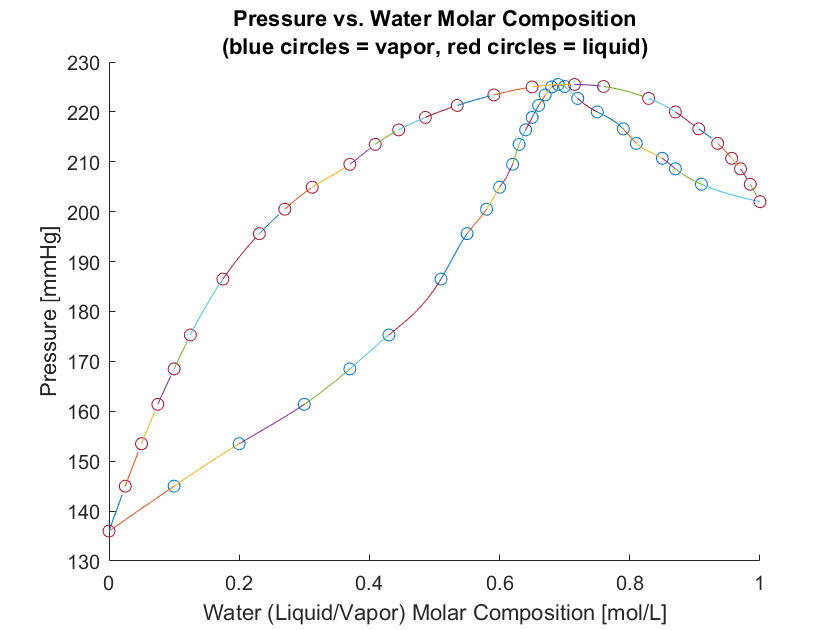

hold off;
title({'Pressure vs. Water Molar Composition';'(blue circles = vapor, red circles = liquid)'})
xlabel('Water (Liquid/Vapor) Molar Composition [mol/L]')
ylabel('Pressure [mmHg]')

**Part B**

Using your models and a root finding method of your choice**, ****calculate ****the molar water composition of the azeotrope** that exists for this binary system.

For the liquid model, I know that a pressure of 180 mmHg comes between a molar composition value of 0.125 and 0.175 mol/L and for the vapor model, I know that this pressure comes between a molar composition value  of 0.43 and 0.51 mol/L. I will take the cubic spline models for each from part a, subtract 180, and find the root of the models to calculate the molar water composition of the azeotrope using the bisection method.

error_tol = 0.001;
syms x
vapor_f = 108.26 * x - 190.87 * (x - 0.43) ^ 2 + 7345.5 * (x - 0.43) ^ 3 + 128.75 - 180;
vapor_x1 = 0.43;
vapor_p1 = double(subs(vapor_f,x,vapor_x1));
vapor_x2 = 0.51;
vapor_p2 = double(subs(vapor_f,x,vapor_x2));

vapor_root = bisection(vapor_f, vapor_x1, vapor_p1, vapor_x2, vapor_p2, error_tol)

vapor_root = 0.4716


liquid_f = 259.57 * x - 772.45 * (x - 0.125) ^ 2 + 1221.6 * (x - 0.125)^ 3 + 142.85 - 180;
liquid_x1 = 0.125;
liquid_p1 = double(subs(liquid_f,x,liquid_x1));
liquid_x2 = 0.175;
liquid_p2 = double(subs(liquid_f,x,liquid_x2));

liquid_root = bisection(liquid_f, liquid_x1, liquid_p1, liquid_x2, liquid_p2, error_tol)

liquid_root = 0.1442

The composition of the azeotrope is 0.4716 molar water vapor and 0.1442 molar liquid water.

**Part C**

Using your models, **calculate the amount (moles) and compositions (water mole fraction)** of the equilibrium liquid (Knockout™ product) obtained at a pressure of 180 mm Hg resulting from separating 20 moles of whiskey.

The 20 moles of whiskey are 30% water.

whiskey_water = 0.3 * 20

whiskey_water = 6

This gives us 6 moles of water. 

From part b, we know that the vapor is 0.4716 molar water and the Knockout, or liquid, is 0.1442 molar water. 

This gives us the following equations:

L + V = 20

0.4716 * V + 0.1442 * L = 6

Solving for L in the first equation, we get

L = 20 - V

to substitute into the second equation.

0.4716 * V + 0.1442 * (20 - V) = 6

Solving for V:

0.4716 * V + 2.884 - 0.1442 * V = 6

0.3272 * V = 3.116

V = 9.523 moles

Substituting into the equation for L:

L = 20 - 9.523

L = 10.477 moles

**Functions**

function S = cubic_spline(x1, y)
m = length(x1);
n = length(y);

if m ~= n
    error('Error: x and y have different dimensions.');
elseif m < 3
    error('Error: not enough points to create a cubic spline.');
else
    scatter(x1,y);
    hold on;
    [A, B, C, D] = spline_coeff(x1,y); 
    S = zeros(m, 1);
    for i = 1:m-1
        a = double(A(i));
        b = double(B(i));
        c = double(C(i));
        d = double(D(i));
        digits(5)
        syms x
        fprintf('Valid from x = %.4f to %.4f', x1(i), x1(i + 1))
        f = vpa(a) + (vpa(b) * (x - vpa(x1(i)))) + (vpa(c) * ((x - vpa(x1(i))) ^ 2)) + ...
            (vpa(d) * ((x - vpa(x1(i))) ^ 3))
        vals = x1(i):0.01:x1(i+1);
        x = vals;
        plot(vals, subs(f));
        hold on;
    end
end
end

function H = h_matrix(x)
n = length(x);
H = zeros(n,n);
H(1,1) = 1;
H(n,n) = 1;
for i = 2:n-1
    for j = 1:n
        if j == i
            H(i, j) = double(2 * ((x(i) - x(i - 1)) + (x(i + 1) - x(i))));
            H(i, j - 1) = double(x(i) - x(i - 1));
            H(i, j + 1) = double(x(i + 1) - x(i));
        end
    end
end
end

function C = k_matrix(x, y)
m = length(x);
n = length(y);
if m ~= n
    error("Error: x and y have different dimensions.");
else
    K = zeros(m,1);
    for i = 2:m-1
        h1 = double(x(i + 1) - x(i));
        h0 = double(x(i) - x(i - 1));
        a2 = double(y(i + 1));
        a1 = double(y(i));
        a0 = double(y(i - 1));
        K(i,1) = double(((3 * (a2 - a1)) / h1) - ((3 * (a1 - a0)) / h0)); 
    end
    H = h_matrix(x);
    C = H\K;
end
end

function [A, B, C, D] = spline_coeff(x, y)
m = length(x);
n = length(y);
if m ~= n
    error('Error: x and y have different dimensions.');
else
    B = zeros(length(y)-1,1);
    D = B;
    C = k_matrix(x,y);
    A = y;
    for i = 1:m-1
        h = (x(i + 1) - x(i));
        B(i,1) = double(((A(i + 1) - A(i)) / h) - (((C(i + 1) + 2 * C(i)) * h) / 3));
        D(i,1) = double((C(i + 1) - C(i)) / (3 * h));
    end
end
end

function x_root = bisection(f, x1, y1, x2, y2, error_tol)
root = 1;
if x1 > x2 
    error('Error: x1 > x2.');
elseif ((y1 > 0) && (y2 > 0)) || ((y1 < 0) && (y2 < 0))
    error('Error: y1 and y2 have the same sign.');
else
    while abs(root) > error_tol
        x_root = (x2 + x1)/2;
        x = x_root;
        root = double(subs(f));
        if (y1 > 0) && (root >= 0)
            x1 = x;
        elseif (y1 < 0) && (root <= 0)
            x1 = x;
        else
            x2 = x;
        end
    end
end
end